% Simulation of linear system of monocopter with flaps
clc
clear all
close all

% load gyro_x_flap.mat
% load gyro_y_flap.mat
% load gyro_x_flap_quat.mat
% load gyro_y_flap_quat.mat
% load jerk_scaling_factor_x.mat
% load jerk_scaling_factor_y.mat

 
% load ka_flap.mat
% load ka_flap_NDI.mat


## Parameters

motor_scaling = 0.135/4;
J = 3.2284E-6*motor_scaling; % moment of inertia of the rotor
b = 3.5077E-6*motor_scaling; % motor viscous friction constant 
K = 0.0274*motor_scaling; % electromotive force constant, motor torque constant 
R = 4*motor_scaling; % electric resistance 
L = 2.75E-6*motor_scaling; % electric inductance  
Jxx = 0.0005713683; % symmetrical so most of it is abt x so therefore Jxx
Jzz = 0.0005987519;
pitch = 41; % deg
pitch = abs(pitch);
plot_variable = 10;
% (bod pitch * ka * motor rpm) contributes to lift force for disk torque due to total pitch generated
ka = 1; % .01,.03,.05,.07,.09,.11,.13
ka = ka*plot_variable; % x1, x2, x3, x4, x5...all the way to x13, default is x 10
rps = -22.0440;
rps_squared = rps^2;
cl = 0.11; % naca 0006
cd = 0.023; % naca 0006
g = 9.81;
rho = 1.225;
radius = 0.26;
chord_length = 0.12;
mass = 0.04376;
altitude = 1.25;

% for x:
% 1.5 - 0.5
% 1.25 - 0.5
% 1.0 - 0.5

% for y:
% 2.0 -  0.85
% 1.75 - 0.9 
% 1.5 - 0.95
% 1.25 - 1.05
% 1.0 - 1.2

torque_w_mass = radius*((cl*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6));
drag_rotation = (cd*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6*mass);
moving_axis = 'x';

if moving_axis == 'x'
    com = 1/(-(g + drag_rotation)); % omega abt y is negative (roll) linear acc x
elseif moving_axis == 'y'
    com = 1/((g + drag_rotation)); % omega abt x is positive (pitch) linear acc y
end

linesize = 3;
Fontsize = 20;

t = 0:0.01:5;
% monocopter precession is like a speed booster lol
if moving_axis == 'x'
    %jerk_scaling_factor_x = jerk_scaling_factor_x*0.256 % impt, for x coordinates needs to scale down up 0.5
    jerk_scaling_factor_x = 0.5;
    u3 = 1/3*(sin((2.2*t)-(pi/2))); % omega abt y, linear acc x
    u = sin((2.2*t)-(pi/2)); % omega abt y, linear acc x
    % u3 = jerk_scaling_factor_x.*u3; % omega abt y, linear acc x
    % u = jerk_scaling_factor_x.*u; % omega abt y, linear acc x

elseif moving_axis == 'y'
    %jerk_scaling_factor_y = jerk_scaling_factor_y*0.8
    %jerk_scaling_factor_y = 0.95;
    jerk_scaling_factor_y = 1.5 + -0.34*(altitude); % gain scheduling
    u3 = 1/3*sin((2.5*t)-(pi)); % omega abt x, linear acc y
    u = sin((2.5*t)-(pi)); % omega abt x, linear acc y
    % u3 = jerk_scaling_factor_y.*u3; % omega abt x, linear acc y
    % u = jerk_scaling_factor_y.*u; % omega abt x, linear acc y

end


%% servo and angular acceleration feedback
omega_dot = torque_w_mass/Jxx;
s = tf('s');
max_rpm = 11600 * 4.2

max_rpm = 48720

min_rpm = max_rpm/2;
hovering_rpm = max_rpm*3/4

hovering_rpm = 36540

remaining_rpm = max_rpm - hovering_rpm %tamp

remaining_rpm = 12180

motor = K/(((J*s+b)*(L*s+R)+K^2)); % sam no integrator at the bottom, unlike the flapped one  
H_motor = 1; % for sam, lpf is needed
H_omega_dot_tf = 1; % lpf is needed and tuned here for indi, ndi is better only  
% H_omega_dot_tf = 0.0;
mtf = motor/(1+(motor*H_motor)); % dun use feedback....cos the hs is different n not one
isstable(mtf)

ans = logical
   1


pole(mtf)

ans = 1.0e+06 *

   -1.4545
   -1.3886
   -0.0659
   -0.0001


% omega_dot_tf = stf; % ndi
omega_dot = mtf*omega_dot;
% omega_dot_tf = omega_dot/(1+(omega_dot*H_omega_dot_tf)); % indi
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

%[omega_dot_controller,info] = pidtune(omega_dot,'PID');
omega_dot_tf = feedback(omega_dot,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)
isstable(omega_dot_tf)

ans = logical
   1


pole(omega_dot_tf)

ans = 1.0e+07 *

  -0.0727 + 1.9806i
  -0.0727 - 1.9806i
  -0.1454 + 0.0000i
  -0.0000 + 0.0000i



%% to simulate step input of a single motor
% max_omega_dot = 0.65/2; % for 1 m/s
% t = 0:0.001:0.15;
% Config = RespConfig('Amplitude',1);
% step(mtf, t, Config) % step function here is in the form of a servo angle 
% ylabel('RPM')
% title('Response to a Step Reference')
%legend('Kp = 1',  'Kp = 11',  'Kp = 21')


[omega_dot_pi,info_d] = pidtune(mtf*torque_w_mass,'PID')

omega_dot_pi =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.709, Ki = 7.85e+04, Kd = 4.63e-07
 
Continuous-time PID controller in parallel form.
Model Properties


info_d = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.2852e+05
           PhaseMargin: 73.9858


disturbance_torque_tf = 1/(Jxx+(H_omega_dot_tf*mtf*torque_w_mass)) % w feedback

disturbance_torque_tf =
 
  1.023e-28 s^4 + 2.975e-22 s^3 + 2.257e-16 s^2 + 1.363e-11 s + 8.063e-10
  -----------------------------------------------------------------------
   5.843e-32 s^4 + 1.7e-25 s^3 + 2.308e-17 s^2 + 3.338e-11 s + 1.977e-09
 
Continuous-time transfer function.
Model Properties


%disturbance_torque_tf = ((s^2)*com)/(((s^2)*com)+(H_omega_dot_tf*omega_dot)) % w feedback
% disturbance_torque_tf = 1/Jxx % wo feedback
dt = 0:0.001:0.2;
isstable(disturbance_torque_tf)

ans = logical
   1


pole(disturbance_torque_tf)

ans = 1.0e+07 *

  -0.0727 + 1.9806i
  -0.0727 - 1.9806i
  -0.1454 + 0.0000i
  -0.0000 + 0.0000i


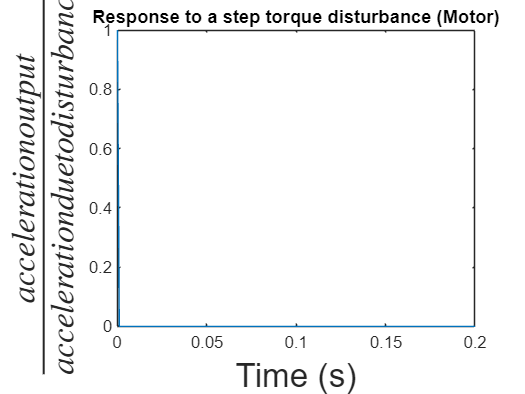

Config = RespConfig('Amplitude',1);
disturbance = step(disturbance_torque_tf, dt, Config); % step function here is in the form of a servo angle 
plot(dt,disturbance/(1/Jxx))
ylabel('$\frac{acceleration output}{acceleration due to disturbance}$','Interpreter','latex','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a step torque disturbance (Motor)')

% snap
snap = (s^2)*com*omega_dot*(1/(s^2))*1/com; % snap only
%[snap_controller,snap_info] = pidtune(snap,'PD'); % controller only needed for omega abt y, linear acc x
snap_tf = feedback(snap,1); % jerk and snap INDI
isstable(snap_tf)

ans = logical
   0


pole(snap_tf)

ans = 1.0e+07 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.0727 + 1.9806i
  -0.0727 - 1.9806i
  -0.1454 + 0.0000i
  -0.0000 + 0.0000i




snap = lsim(snap_tf,u3,t); % INDI cant be tested

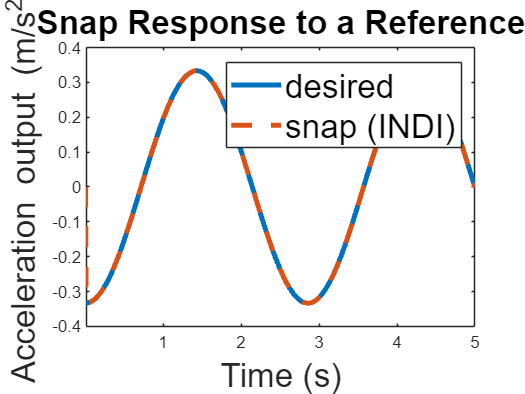

plot (t,u3,'LineWidth',linesize)
hold on
plot(t,snap,'lineStyle','--','LineWidth',linesize)
hold off
xlim([0.011 5])

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Snap Response to a Reference','FontSize',Fontsize)
legend('desired','snap (INDI)','FontSize',Fontsize)